# Network Milestone - Alexander Wang (aw3494), Nick Fiorovanti (nef46)

# ***CHECK WIP_network_model_most_recent.mlx***

## Step 1. Set up Network Representation

% Number of individuals
N = 100;

% Random symmetric matrix
network = randi([0, 1], N);
network = triu(network, 1);
network = network + network';

% Initialize the state of individuals (0 = Susceptible, 1 = Infected)
state = zeros(N, 1);

% Randomly assign a few individuals as Infected
num_initially_infected = 0.05*N;
infected_indices = randperm(N, num_initially_infected);
state(infected_indices) = 1;


## Step 2. Simulate

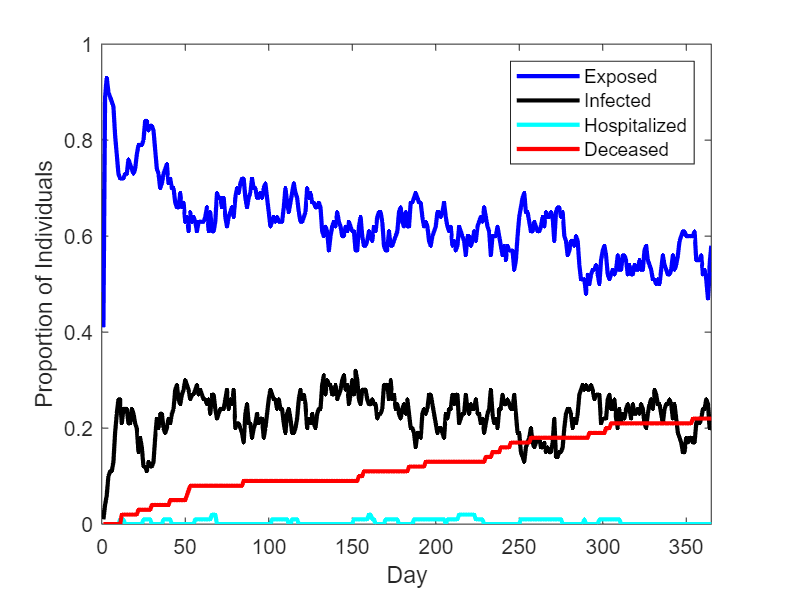

% CUSTOMIZE PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_days = 365;                                 % days
expose_prob = 0.05;                             % exposure prob
infect_prob = 0.04;                             % infection prob (4% was given in paper)
recover_prob = 0.1;                             % recovery prob
num_exposed = zeros(num_days, 1);               % Vector of exposed individuals each day
num_infected = zeros(num_days, 1);              % Vector of infected individuals each day
% death_rate = 0.0028;                          % OLD DEATH RATE: gross mortality rate https://www.worldometers.info/coronavirus/coronavirus-death-rate/
quarantining_rate = 0.75;                       % quarantining rate  - https://thehill.com/changing-america/well-being/medical-advances/491760-3-in-4-americans-say-they-are-self-isolating-in/#:~:text=Approximately%2075%20percent%20of%20U.S.%20residents%20are%20self-isolating,coronavirus%20and%20is%20being%20enforced%20across%20the%20country.
hospitalization_rate = 0.0015;                  % hospitalization rate https://www.nytimes.com/interactive/2023/us/covid-cases.html
positive_rate = 0.12875             % Percent Positive Testing: averaged peaks of % positive weekly https://covid.cdc.gov/covid-data-tracker/#trends_weeklyhospitaladmissions_testpositivity_00
% MAKE ASSUMPTION - IF EACH EXPOSED INDIVIDUAL AT-HOME TESTS, AND THEN TESTS POSITIVE, THEY
% SOCIAL DISTANCE AND CANNOT INFECT OTHERS
% ORRRRRR
death_rate = 0.1625;                % percent deaths: averaged peaks of % death attributed to covid https://covid.cdc.gov/covid-data-tracker/#trends_weeklyhospitaladmissions_testpositivity_00
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
state_orig = state;
for l = 1:10
    state = state_orig; 
    for day = 1:num_days                            % For each day...
        for i = 1:N                                 % For each individual...
            if state(i) == 1                        % If they are infected...
                contacts = find(network(i, :));     % Find the individuals they are in contact with...
    %             if rand < quarantining_rate
    %                 contacts = 0;
    %                 state(i) = inf;
    %             else
                for j = contacts                    % For each contact...
                    exposed_diceroll = rand;
                    if state(j) == 0                % If the contact is susceptible...
                        if exposed_diceroll < expose_prob       % They become exposed with expose_prob
                            state(j) = 3; % NEED TO CHANGE FROM 1 TO 3 BECAUSE 1 ALREADY REPRESENTS INFECTED... EXPOSED NEEDS IS DIFFERENT         
                        end
                    end
                end
    %             end
            
                infected_diceroll = rand; 
                if infected_diceroll < infect_prob               % The exposed individual becomes infected with infect_prob
                    state(i) = 2;
                end
            elseif state(i) == 3 % IF EXPOSED, BUT NOT YET INFECTED OR SUSCEPTIBLE, 
                % ADDED IN SEPARATE NUMBER FOR EXPOSED COMPARED TO SUSCEPTIBLE, INFECTED, HOSPITALIZED, EXPOSED, AND DEAD
                infected_diceroll = rand; 
                if infected_diceroll <  infect_prob
                    state(i) = 2;
                end
            elseif state(i) == 2 || state(i) == 4                   % If the is exposed individual becomes infected or the individual is hospitalized...
                reaper_diceroll = rand; 
                if reaper_diceroll < recover_prob              % The infected individual recovers with recover_prob
                    state(i) = 0;
                elseif reaper_diceroll > (1-hospitalization_rate) % hospitalization 
                    state(i) = 4; 
                elseif reaper_diceroll > (1-death_rate) && rand < (1-hospitalization_rate) % death
                    state(i) = NaN;
                end 
            end
        end  
        % Record the number of exposed and infected individuals
        num_susceptible(day) = sum(state == 0)
        num_exposed(day) = sum(state == 1);
        num_infected(day) = sum(state == 2);
        num_deceased(day) = sum(isnan(state));
        num_hospitalized(day) = sum(state == 4);
    %    num_quarantine(day) = sum(isinf(state));
    end

% Store all of the simulated data for this iteration in the accumulation
% variables
num_exposed_accumulated(l,:) = num_exposed';
num_infected_accumulated(l,:) = num_infected';
num_deceased_accumulated(l,:) = num_deceased'; 
num_hospitalized_accumulated(l,:) = num_hospitalized';
end

% Plot the number of exposed and infected individuals over time
figure;

% Plot exposed proportion 
plot(1:num_days, num_exposed/N, 'Color', 'Blue', 'DisplayName', 'Exposed', 'LineWidth', 2);
hold on;

% Plot infectious proportion
plot(1:num_days, num_infected/N, 'Color', 'Black', 'DisplayName', 'Infected', 'LineWidth', 2);

% Plot hospitalized proportion
plot(1:num_days, num_hospitalized/N, 'Color', 'Cyan', 'DisplayName', 'Hospitalized', 'LineWidth', 2)

% Plot deceased proportion
plot(1:num_days, num_deceased/N, 'Color', 'Red', 'DisplayName', 'Deceased', 'LineWidth', 2)

% Label figure
xlabel('Day');
ylabel('Proportion of Individuals');
xlim([0 num_days])
legend()

## Summary Stats Over Repetitions

% Mean Peak Exposed
peak_exposed = mean(max(num_exposed_accumulated));
% Mean Peak Infected 
peak_infected = mean(max(num_infected_accumulated));
% Mean Peak Deceased
peak_deceased = mean(max(num_deceased_accumulated));
% Mean Peak Hospitalized
peak_hospitalized = mean(max(num_hospitalized_accumulated));

avg_tot_infec = 2.2706e+04


% Over Iterations, Find Time for Peaks
for z = 1:1000
    row_exposed_peak= find(num_exposed_accumulated(z,:) == max(num_exposed_accumulated(z,:)));
    row_infectious_peak = find(num_infected_accumulated(z,:) == max(num_infected_accumulated(z,:)));
    row_deceased_peak = find(num_deceased_accumulated(z,:) == max(num_deceased_accumulated(z,:)));
    row_hospitalized_peak = find(num_hospitalized_accumulated(z,:) == max(num_hospitalized_accumulated(z,:)));
    peak_times(z, :) = [row_exposed_peak(1), row_infectious_peak(1), row_deceased_peak(1), row_hospitalized_peak(1)];
    num_peaks(z,:) = [numel(row_exposed_peak), numel(row_infectious_peak), numel(row_deceased_peak), numel(row_hospitalized_peak)];
end

% Find Averages of Iterations for Times for Peaks
avg_peak_times = mean(peak_times);
exp_peak_times_avg = avg_peak_times(1); 
inf_peak_times_avg = avg_peak_times(2); 
deceased_peak_times_avg = avg_peak_times(3);
hospitalized_peak_times_avg = avg_peak_times(4); 

% Create table of findings
T3 = table([peak_exposed; exp_peak_times_avg], [peak_infected; inf_peak_times_avg], [peak_deceased; deceased_peak_times_avg], [peak_hospitalized; hospitalized_peak_times_avg]);
T3.Properties.RowNames = {'Peak # Individuals', 'Day @ Peak'};
T3.Properties.VariableNames = {'Exposed', 'Infected', 'Deceased', 'Hospitalized'};
disp(T3)

                          Exposed    Infected    Deceased    Hospitalized
                          _______    ________    ________    ____________

    Peak # Individuals    74.962      36.986      20.811        14.088   
    Day @ Peak             2.949      78.146       344.8        326.39   

